 MATLAB提供了专门用于求离散系统频响特性的函数freqz(),调用freqz()的格式有一下两种：

   （1）[H,w] = freqz(B,A,N)

B和A分别为离散系统的系统函数的分子、分母多项式的系数向量，N为正整数，返回向量H则包含了离散系统频响在0-PI范围内N个频率等分点的值，向量w则包含0-PI范围内N个频率等分点。调用中若N默认，默认值为512。

（2）[H,w] = freqz(B,A,N,'whole')

    该调用格式将计算离散系统在0—2*PI范内的N个频率等分点的频率响应的值；一般看完整的相频响应要用’whole‘。

（3）注意freqz和freqs的区别。

    因此，可以先调用freqz()函数计算系统的频率响应，然后利用abs()和angle()函数及plot()函数，即可绘制出系统的频响曲线。

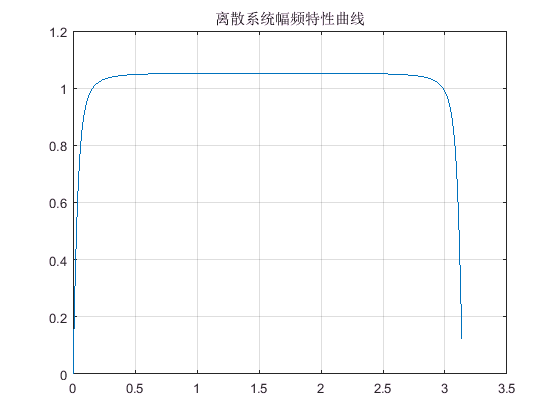

clc;
clear;

B = [1 0 -1];
A = [1 0 -0.9];
[H,w] = freqz(B,A); %just 0~pi range is fairly fine.

Hf = abs(H);
Hx = angle(H);

figure(1);
plot(w,Hf);
title('离散系统幅频特性曲线');
grid on;

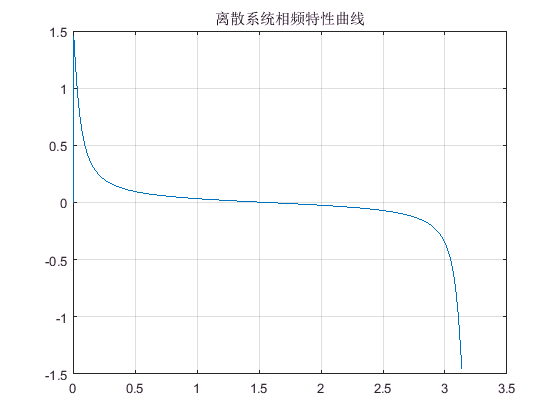


figure(2);
plot(w,Hx);
title('离散系统相频特性曲线');
grid on;

接下来要转换成真正的频率域显示(对吗？？w=2*pi*f/fs)：

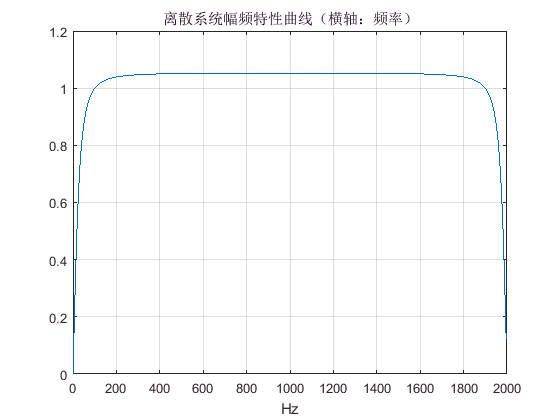

scalar = 2*pi;
T = 1 / 4000 ;
f = w / scalar / T;

figure(3);
plot(f,Hf);
title('离散系统幅频特性曲线（横轴：频率）');
xlabel('Hz');
grid on;